# 输出目标点位用于声场计算的环境文件

@SYSU Lu Yiyang

## 初始化

clear; close all; clc;
tmp = matlab.desktop.editor.getActive;
index = strfind(tmp.Filename, '\') ;
pathstr = tmp.Filename(1:index(end)-1);
cd(pathstr);
addpath(pathstr); addpath([pathstr '\function']);

## 读取数据库 地形、声速剖面

etop_dir = 'etopo1.mat';   woa18_dir = 'WOA18_mat';
% 从数据集中加载地形数据和声速剖面数据
[ETOPO, WOA18] = load_data(etop_dir, woa18_dir);
%clear
clear etop_dir; clear woa18_dir; clear index; clear pathstr; clear tmp;

## 目标点位参数

%经纬度范围
Lat = [10,25];
Lon = [110,125];
%声源点位
coordS.lon = 116; 
coordS.lat = 15;
depth = get_bathm(ETOPO, coordS.lat, coordS.lon)

depth = 4.2260e+03

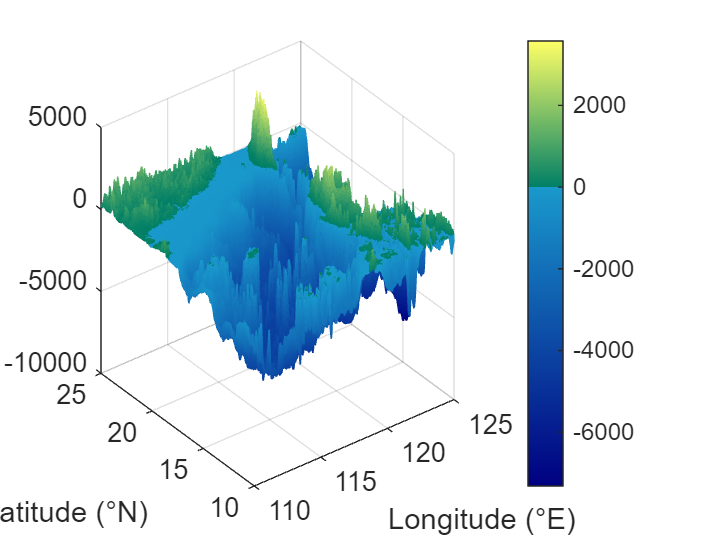

%测线方向及长度
azi  = 0;
rmax = 30; 
%计算最远距离接收点经纬度
coordE = [];
[coordS, coordE, rmax, azi] = coord_proc(coordS, coordE, rmax, azi);
%地理信息展示
plotgeomap(Lat, Lon);

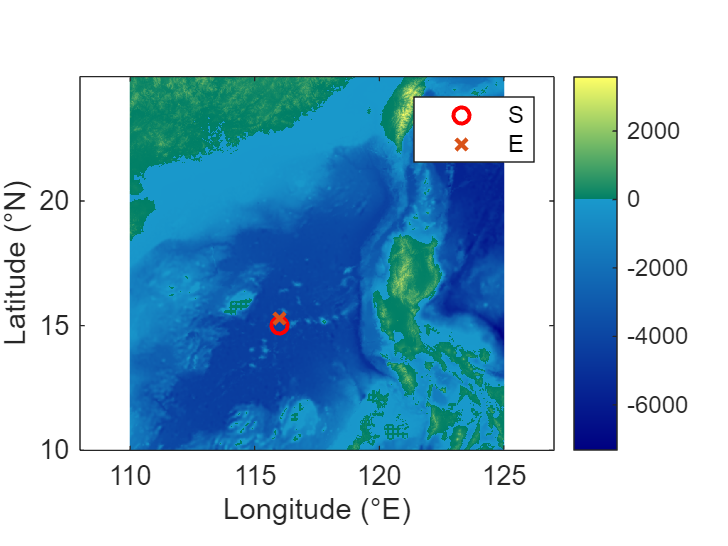

plot(coordS.lon, coordS.lat, 'ro', 'LineWidth', 1.5, 'DisplayName', 'S');
plot(coordE.lon, coordE.lat, 'x' , 'LineWidth', 1.5, 'DisplayName', 'E');
legend;

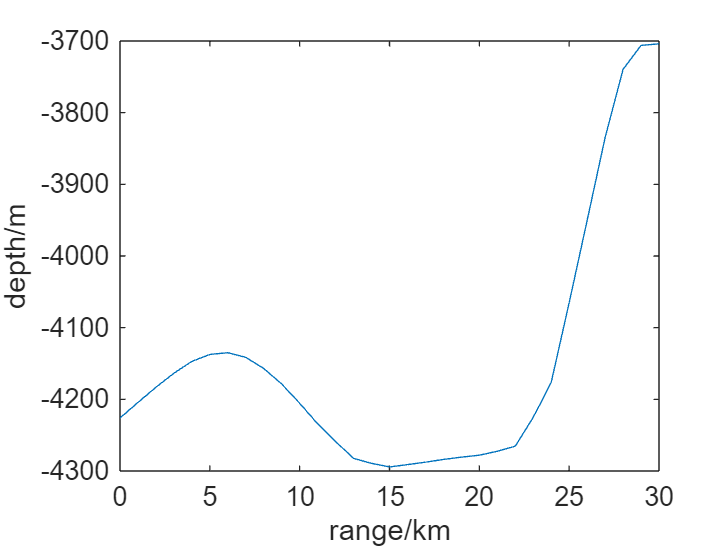

clear Lat; clear Lon;

n=ceil(rmax)+1;
lat=linspace(coordS.lat,coordE.lat,n);
lon=linspace(coordS.lon,coordE.lon,n);
r=linspace(0,rmax,n);
depth = get_bathm(ETOPO, lat, lon);
figure
plot(r,-depth);
xlabel('range/km');
ylabel('depth/m');

## 环境参数设置

runtype = 'A';   % 5 character

%% 海面板块
top_option = 'CFFT';% 5 character
sea_state_level = 0;   % n级海况
freq = 500;   % 计算中心频率
freqvec = 500;   % 反射系数计算宽带频率
%海面高程
lambda = 100;
height = 5;

% 声速板块
MouthIdx = 1;          % 声速剖面采样月份
[~, ssp_raw, ~] = get_env(ETOPO,WOA18,coordS.lat,coordS.lon, MouthIdx); % 获取平均声速剖面
ssp_top = ssp_raw(1,2); % top speed
ssp_bot = ssp_raw(end,2); % bottom speed

% 海底板块
bottom_option = 'F*'; % 2 character
base_type = 'IMG';  % 底质类型
alpha_b = 0.05;

% 阵列板块
BeamWidth =0;     % BeamWidth为新的波束宽度
BeamWidth(end+1) = 360; % 360度表示无指向性


SourceRange = 0;
SourthDepth = 10;  %声源深度
ReceiveDepth = 100; %接收深度
ReceiveRange = rmax;  %%%%%设置此参数以减少计算量
ri = 0;  % 接收距离间隔/km
zi = 0;  % 接收深度间隔/m


% 波束板块
alpha = 90;
theta=-90:270;
DI=ones(1,length(theta));
beam_option.Type = 'CS';% 2 character
beam_option.epmult = 0.3;
beam_option.rLoop  = 1;
beam_option.Nimage = 1;
beam_option.Ibwin  = 1;


## 参数文件输出

%文件命名
envfil = ['TEST_sd',num2str(SourthDepth),'_rd',num2str(ReceiveDepth),'_lon',num2str(coordS.lon),'_lat',num2str(coordS.lat)];
cd 'D:\code\matlab\underwateracoustic\bellhop_fundation\out'
% if exist(envfil, 'dir') ~= 7
%     mkdir(envfil);
% end

%% 海面建模ati
if contains(top_option,'*')==1
write_altimetry(lambda,height,rmax,ri,envfil)
end
%% 声源指向性sbp
if contains(runtype,'*')==1
SourceBeam(BeamWidth,theta,DI,envfil)
end
%% 海面反射trc
a=strfind(top_option,'F');
if ismember(2,a)==1
TopReCoe(freqvec, ssp_top, sea_state_level, sprintf('%s', envfil));
end
%% 海底反射brc
if contains(bottom_option,'*')==1
RefCoeBw(base_type, sprintf('%s', envfil), freqvec, ssp_bot, alpha_b);
end
%% 环境 env、bty、ssp
call_Bellhop_surface_more(ETOPO,WOA18,envfil, freq, SourthDepth,ReceiveDepth, MouthIdx, coordS, coordE, ...
    SourceRange,ReceiveRange, ri, zi, runtype, top_option,bottom_option,beam_option,-alpha,alpha);
